# Main

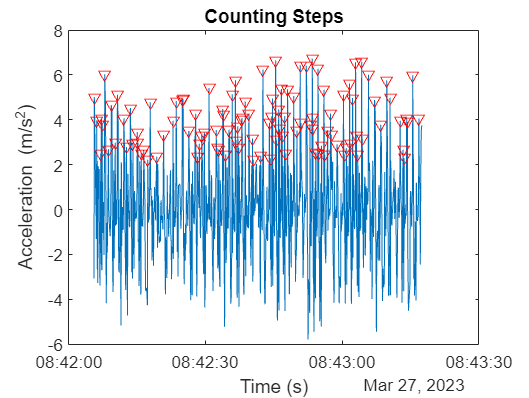

clc, clear;
%Need to put it in the same timetable: same timebase
% Think about what data the classification needs
% Look at moving average for each variable (mean). Can add standard
% deviation. Look at minimum and max accel and orientation
% Break the data up into chunks

%https://uk.mathworks.com/help/signal/ug/human-activity-recognition-using-signal-feature-extraction-and-machine-learning.html
%Look into the link above for activity recognition etc instead of what I
%have done

% Loads mat file into workspace and stores its data
fileName = "Step100.mat";
fileData = openFile(fileName);
walk_dataAccel = fileData.Acceleration;
walk_dataOrien = fileData.Orientation;
clear fileData fileName;

% Loads mat file into workspace and stores its data
fileName = "Sitting1.mat";
fileData = openFile(fileName);
sit_dataAccel = fileData.Acceleration;
sit_dataOrien = fileData.Orientation;
clear fileData fileName;

[walk_dataAccel, walk_dataOrien] = DataClean(walk_dataAccel, walk_dataOrien);

%Create a function for Step Counter and plotting it
stepCount = steps(walk_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 108

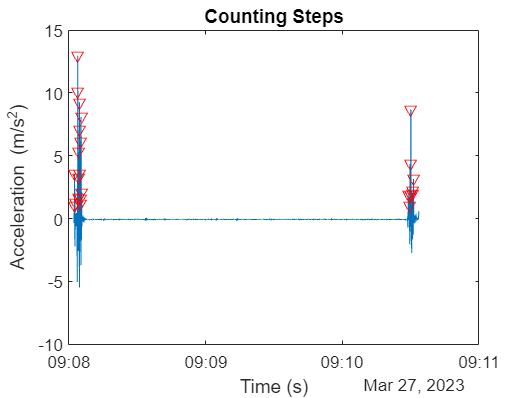

clear stepCount;
stepCount = steps(sit_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 25


clear stepCount;

% Extract Features from timetables
featureData = extractFeat(walk_dataAccel,walk_dataOrien);
Classification = categorical(repmat("Walking",height(featureData),1));
extractedData = addvars(featureData,Classification);

clear featureData Classification;

featureData = extractFeat(sit_dataAccel,sit_dataOrien);
Classification = categorical(repmat("Sitting",height(featureData),1));
featureData = addvars(featureData,Classification);
extractedData = [extractedData; featureData]

extractedData = 91×7 timetable
           Timestamp            Xaccel    Yaccel     Zaccel     Xorien     Yorien    Zorien     Classification
    ________________________    ______    _______    _______    _______    ______    _______    ______________

    27-Mar-2023 08:42:05.000    2.0826    -9.1604     0.1222    -46.104        77    -75.112       Walking    
    27-Mar-2023 08:42:07.500     2.328    -9.4701     1.5057     26.979    69.319    -48.068       Walking    
    27-Mar-2023 08:42:10.000    2.0268    -9.1282     1.6222    -47.051    69.435    -65.737       Walking    
    27-Mar-2023 08:42:12.500    2.9583     -8.899    0.96298      4.456  

clear featureData;
